clear
clc
opengl hardware


%addpath("/Users/louieburns/Library/CloudStorage/OneDrive-UniversityofLeeds/Robotics Coursework/URDFs/Robot_URDF/urdf")  % Louie Path folder
addpath("C:\Users\dnehu\OneDrive - University of Leeds\Robotics Coursework\URDFs\Robot_URDF\urdf")  % Dan path folder

savepath % Save filepath for next time

Robot = importrobot('Robot_URDF.urdf');
showdetails(Robot)

--------------------
Robot: (6 bodies)

 Idx             Body Name      Joint Name      Joint Type             Parent Name(Idx)   Children Name(s)
 ---             ---------      ----------      ----------             ----------------   ----------------
   1                Link_1          Joint1        revolute                 Base_Link(0)   Link_2(2)  
   2                Link_2          Joint2        revolute                    Link_1(1)   Link_3(3)  
   3                Link_3          Joint3        revolute                    Link_2(2)   Link_4(4)  
   4                Link_4          Joint4        revolute                    Link_3(3)   End_Effector_1(5)  End_Effector_2(6)  
   5        End_Effector_1        Joint5_1       prismatic                    Link_4(4)   
   6        End_Effector_2        Joint5_2       prismatic                    Link_4(4)   
--------------------


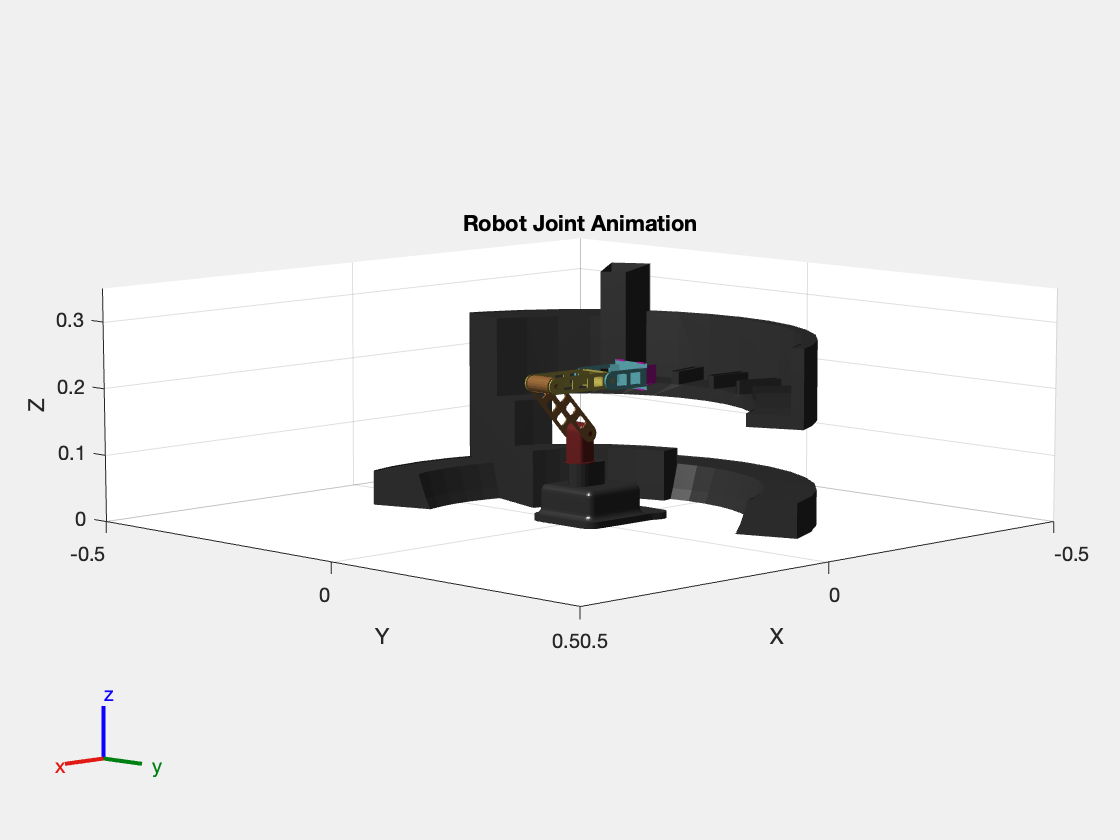


figure;
ax = axes;
show(Robot, homeConfiguration(Robot), "Frames", "off", "Parent", ax);
set(ax, 'ZLim', [0 0.35], 'XLim', [-0.5 0.5], 'YLim', [-0.5 0.5]);
title('Robot Joint Animation');



% Joint names from home configuration
config = homeConfiguration(Robot);
jointNames = {config(1).JointName, config(2).JointName, config(3).JointName, config(4).JointName, config(5).JointName, config(6).JointName};


numJoints = length(jointNames);
angleSteps = 60;
angleRange = 0:angleSteps:360;

for joint1Angle = angleRange

ans =   Axes (Primary) with properties:

             XLim: [-2 2]
             YLim: [-2 2]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.1300 0.1100 0.7750 0.8150]
            Units: 'normalized'

  Show all properties


ans =   Axes (Primary) with properties:

             XLim: [-2 2]
             YLim: [-2 2]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.1300 0.1100 0.7750 0.8150]
            Units: 'normalized'

  Show all properties


ans =   Axes (Primary) with properties:

             XLim: [-2 2]
             YLim: [-2 2]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.1300 0.1100 0.7750 0.8150]
            Units: 'normalized'

  Show all properties


ans =   Axes (Primary) with properties:

             XLim: [-2 2]
             YLim: [-2 2]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.1300 0.1100 0.7750 0.8150]
            Units: 'normalized'

  Show all properties


ans =   Axes (Primary) with properties:

             XLim: [-2 2]
             YLim: [-2 2]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.1300 0.1100 0.7750 0.8150]
            Units: 'normalized'

  Show all properties


ans =   Axes (Primary) with properties:

             XLim: [-2 2]
             YLim: [-2 2]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.1300 0.1100 0.7750 0.8150]
            Units: 'normalized'

  Show all properties


ans =   Axes (Primary) with properties:

             XLim: [-2 2]
             YLim: [-2 2]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.1300 0.1100 0.7750 0.8150]
            Units: 'normalized'

  Show all properties


ans =   Axes (Primary) with properties:

             XLim: [-2 2]
             YLim: [-2 2]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.1300 0.1100 0.7750 0.8150]
            Units: 'normalized'

  Show all properties


ans =   Axes (Primary) with properties:

             XLim: [-2 2]
             YLim: [-2 2]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.1300 0.1100 0.7750 0.8150]
            Units: 'normalized'

  Show all properties


ans =   Axes (Primary) with properties:

             XLim: [-2 2]
             YLim: [-2 2]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.1300 0.1100 0.7750 0.8150]
            Units: 'normalized'

  Show all properties


ans =   Axes (Primary) with properties:

             XLim: [-2 2]
             YLim: [-2 2]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.1300 0.1100 0.7750 0.8150]
            Units: 'normalized'

  Show all properties


Error using newplot (line 48)
Argument must be a scalar handle to an existing graphics object.

Error in robotics.manip.internal.RigidBodyTree/simpleShow (line 1317)
                ax = newplot(parent);

Error in 

    for joint2Angle = angleRange
        for joint3Angle = angleRange
            for joint4Angle = angleRange
                config = homeConfiguration(Robot);

                config(1).JointPosition = deg2rad(joint1Angle);
                config(2).JointPosition = deg2rad(joint2Angle);
                config(3).JointPosition = deg2rad(joint3Angle);
                config(4).JointPosition = deg2rad(joint4Angle); % ← New Joint

                show(Robot, config, "Frames", "off", "Parent", ax)
                set(ax, 'ZLim', [-0.2 0.35], 'XLim', [-0.4 0.5], 'YLim', [-0.4 0.4]);
                
                drawnow;
                pause(0.5);
            end
        end
    end
end
